# Comparación de la calidad de las imágenes

%% set path and load some data
addpath("Calidad-imagen/")

function image_stack = load_image_stack(folder_path)
    % Listar todos los archivos en la carpeta y ordenar
    files = dir(fullfile(folder_path, '*.tif'));
    files = [files; dir(fullfile(folder_path, '*.png'))];
    files = [files; dir(fullfile(folder_path, '*.jpg'))];
    [~, index] = sort({files.name});
    files = files(index);
    
    % Leer la primera imagen para obtener las dimensiones
    first_image = imread(fullfile(folder_path, files(1).name));
    [height, width] = size(first_image);
    
    % Crear una matriz 3D vacía para almacenar las imágenes
    image_stack = zeros(height, width, length(files), 'single');
    
    % Leer el rango de valores para normalización
    max_val = double(max(first_image(:)));  % Valor máximo para normalización

    % Cargar cada imagen en la matriz 3D
    for i = 1:length(files)
        img = imread(fullfile(folder_path, files(i).name));
        % Convertir la imagen a single y normalizar
        image_stack(:, :, i) = single(img) / max_val;
    end
end


Vamos a probar con la imagen original

imagePath1 = '/Users/yi/TFGNotebook/CElegans-FITC';
image_stack1 = load_image_stack(imagePath1);
image_stack1 = image_stack1(1:356, 1:336, 52);

I = imread('deconvolved_CElegans_Julia_CANAL3.png'); %ESTO ES PARA JULIA
single = im2single(I);
image = single;

Computing dcorr: --------------------- -- Computation done -- 


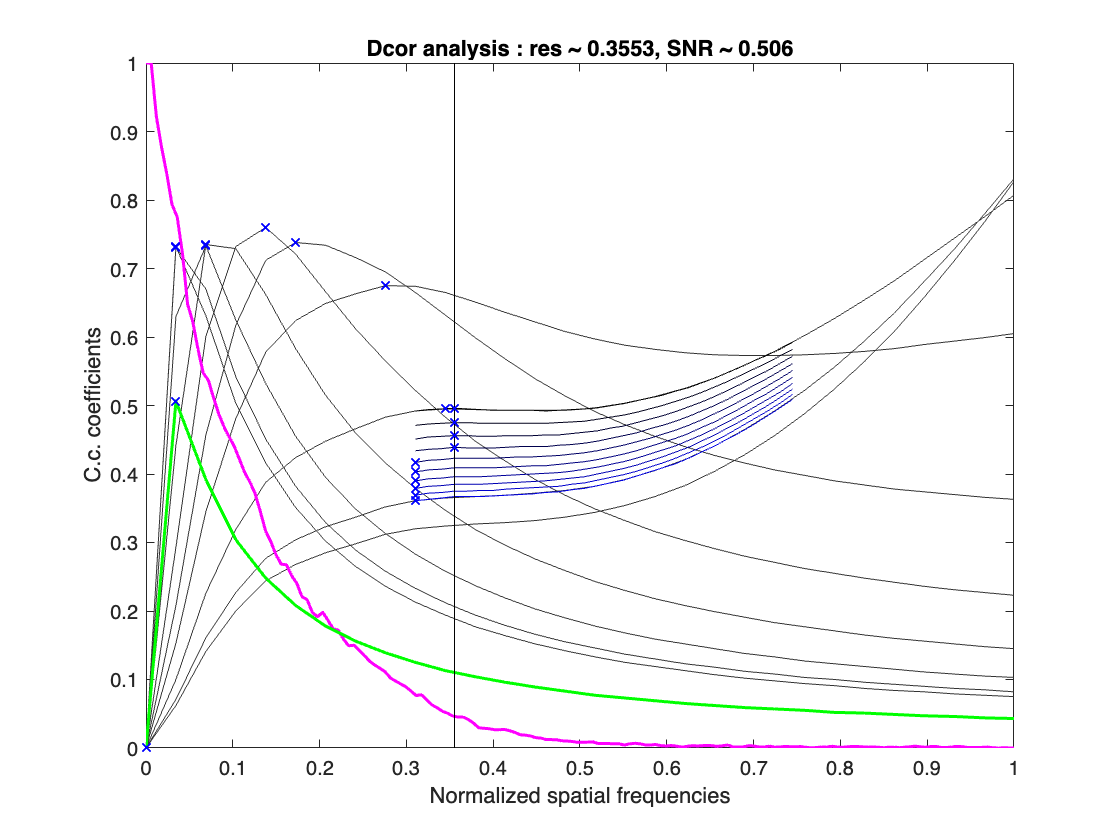

pps = 64; % projected pixel size of 64nm
% typical parameters for resolution estimate
Nr = 25;
Ng = 10;
r = linspace(0,1,Nr);
GPU = 0;

%% apodize image edges with a cosine function over 20 pixels
image_apodizada = apodImRect(image, 20);

%% compute resolution

figID = 100;

if GPU 
    [kcMax,A0] = getDcorr(gpuArray(image_apodizada),r,Ng,figID); gpuDevice(1);
else
    [kcMax,A0] = getDcorr(image_apodizada,r,Ng,figID);
end


disp(['kcMax : ',num2str(kcMax,3),', A0 : ',num2str(A0,3)])

kcMax : 0.355, A0 : 0.506


## SOLO ES NECESARIO HACER EL PRIMER TEST

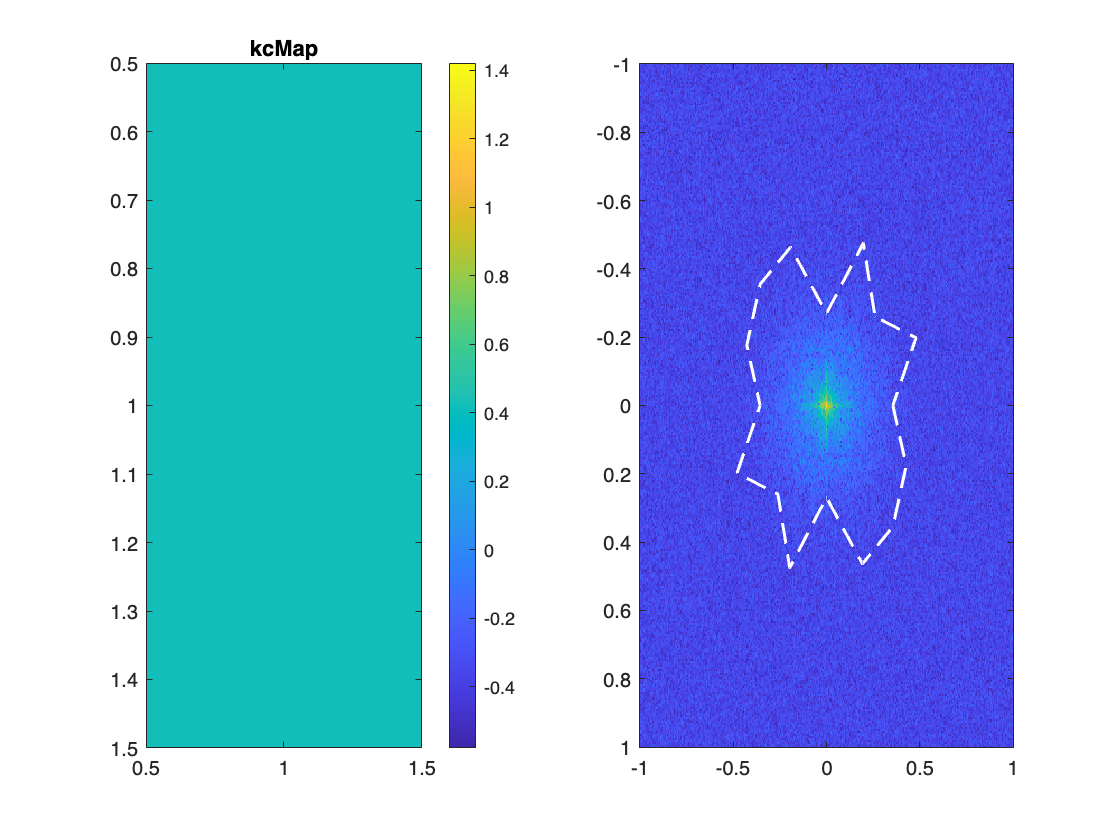

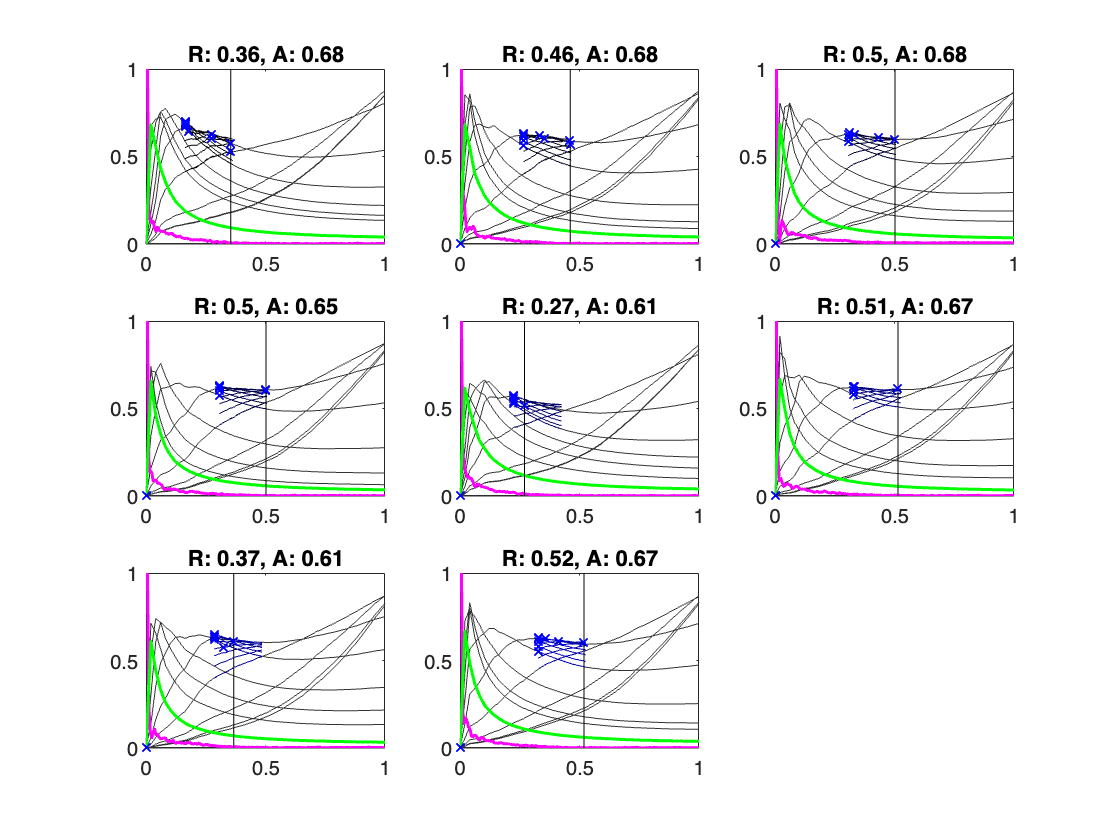

%% sectorial resolution

Na = 8; % number of sectors
figID = 101;
if GPU
    [kcMax,A0] = getDcorrSect(gpuArray(image),r,Ng,Na,figID); gpuDevice(1);
else
    [kcMax,A0] = getDcorrSect(image,r,Ng,Na,figID);
end

Computing dcorr: --------------------- -- Computation done -- 


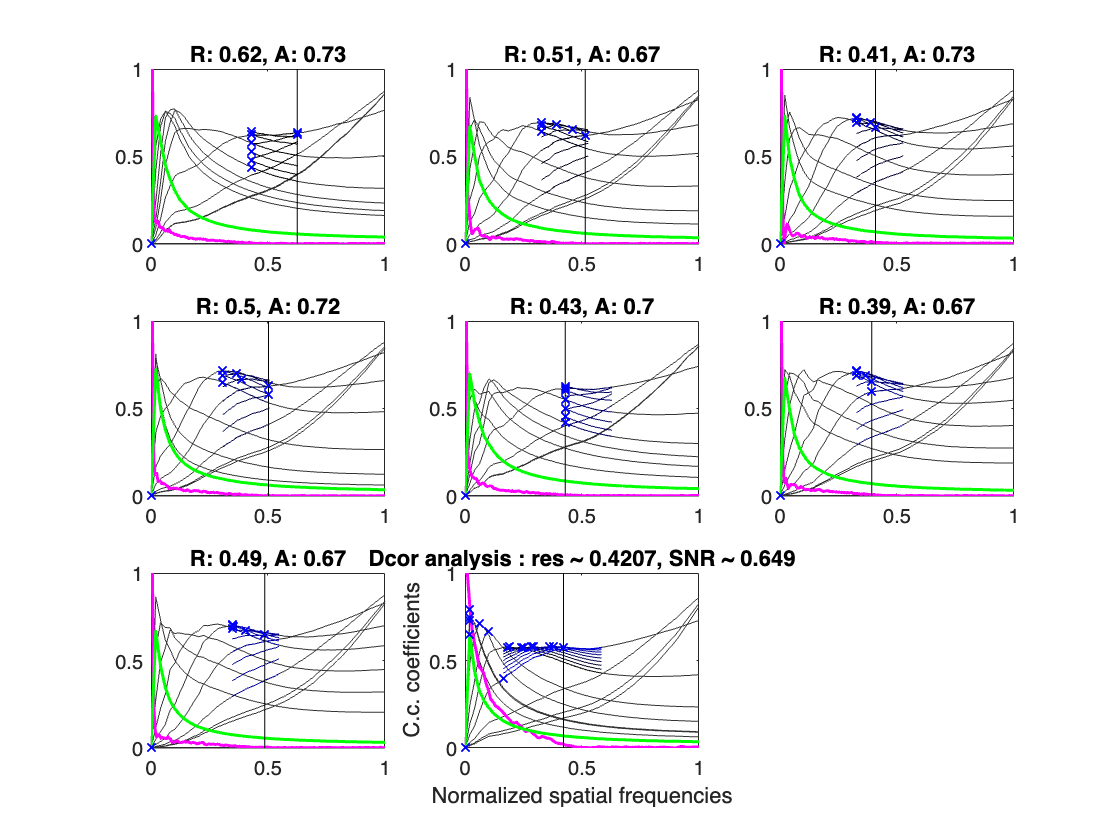

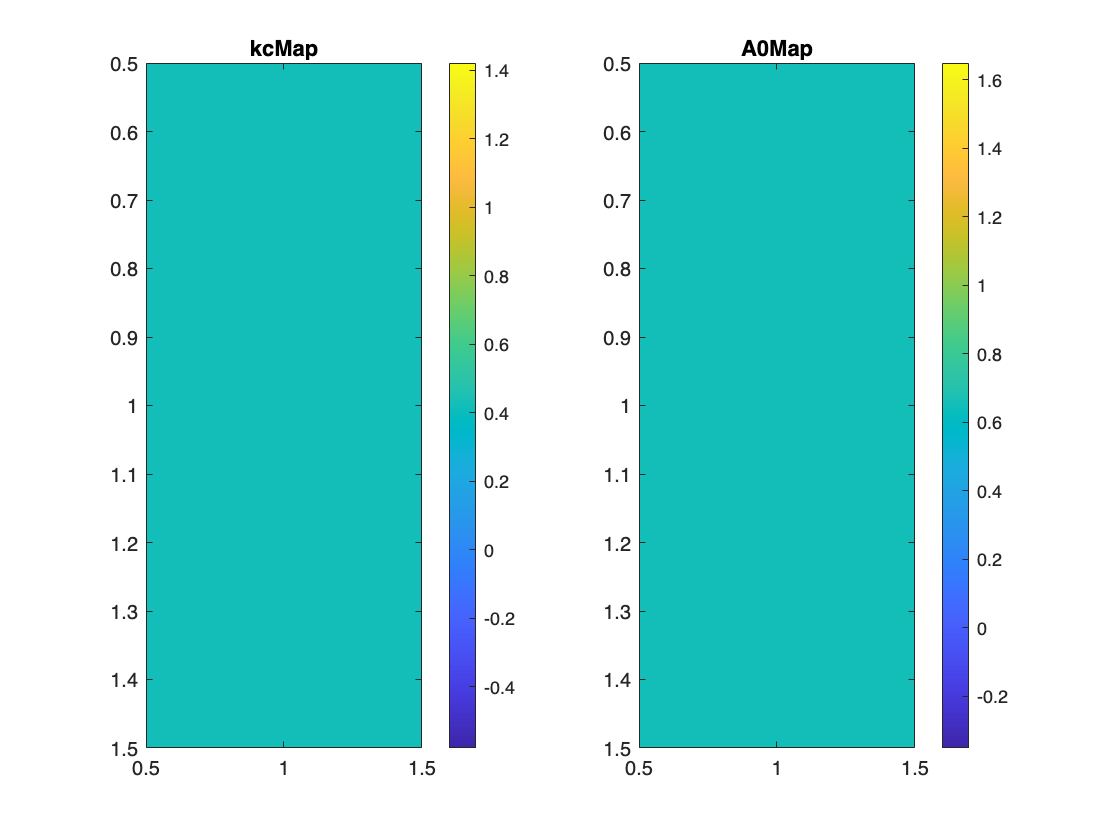


%% Local resolution map

tileSize = 200; % in pixels
tileOverlap = 0; % in pixels
figId = 103;

if GPU 
    [kcMap,A0Map] = getLocalDcorr(gpuArray(image),tileSize,tileOverlap,r,Ng,figID);gpuDevice(1);
else
    [kcMap,A0Map] = getLocalDcorr(image,tileSize,tileOverlap,r,Ng,figID);
end